# **Typical dynamics**

# **22320630**

# **Zhu Chenhao**

## Electric vehicles

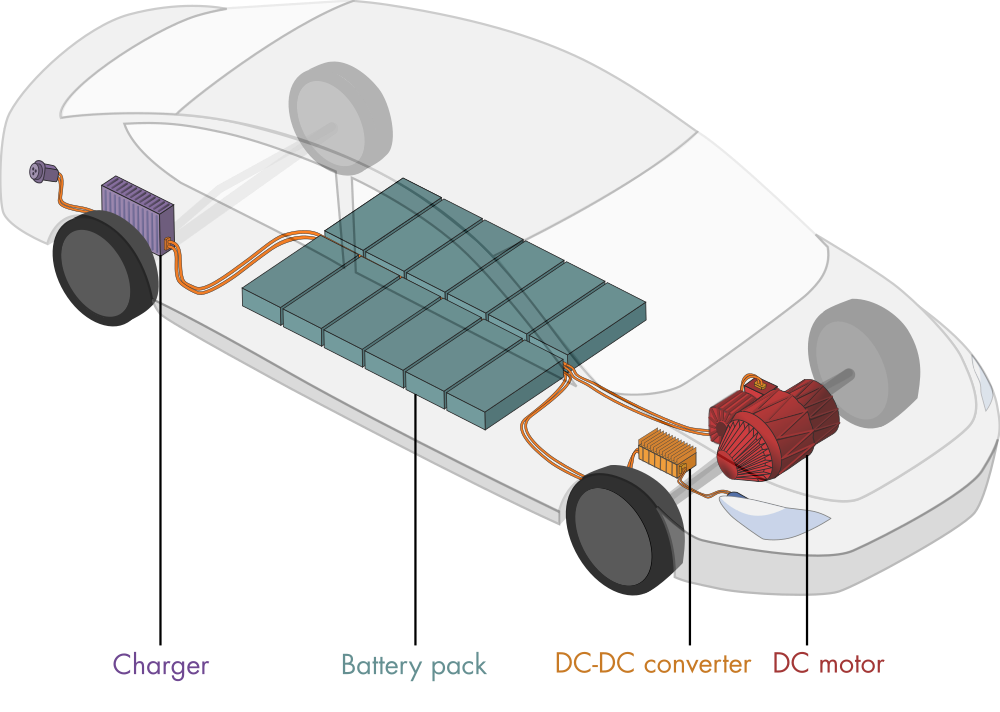Енщ

*Essential components of an electric vehicle*

Electric vehicles (EV) may well be the future of environmentally sustainable travel. But what makes it possible for an EV to be more efficient than a gas vehicle while still providing enough power to accelerate to and maintain high speeds? The answer lies in efficient power electronics. In this module, you will learn about transfer functions and use them to analyze the dynamics of several essential components of an electric vehicle.

# Transfer Function Basics

This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Transfer Function Definition

Consider a dynamic system with a single input function $u(t)$ and a single output function$y(t)$:

    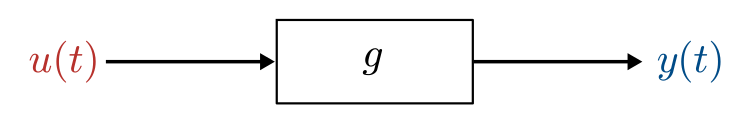

This is known as a **SISO** (Single Input Single Output) system. In general, the system $g$ is defined through a differential equation: $g(u, x, \dot{x}, \ddot{x},  \ldots) = 0$.

The **transfer function** is defined as

    $G(s) = \frac{Y(s)}{U(s)}$,

the ratio of the Laplace transform of the output $Y(s) = \mathcal{L}\{y(t)\}$ to the Laplace transform of the input $U(s) = \mathcal{L}\{u(t)\}$. The transfer function $G(s)$ maps inputs $U$ to outputs $Y$:

     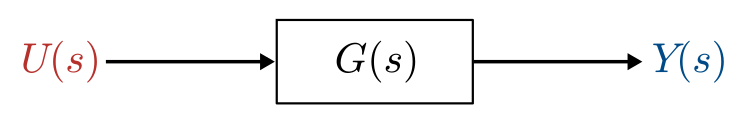

** Example. **Find the transfer function of a mass-spring-damper that is dynamically forced by an arbitrary function $u(t)$. Assume that the system is initially at rest ($x(0) = 0$ and $\dot{x}(0)=0$).

      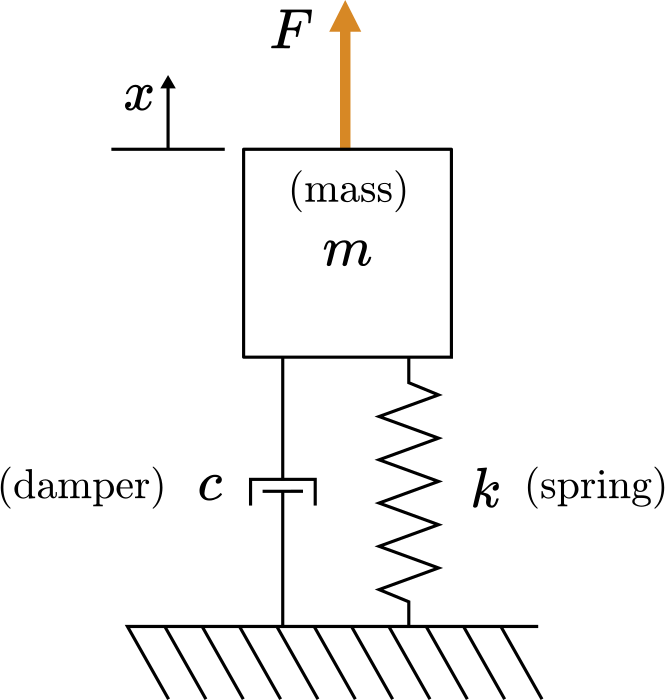

        *Mass-spring-damper diagram*

**Solution. **The equation of motion for a mass-spring-damper is

    
$$m \ddot{x} + c \dot{x} + k x = u$$


Using the properties of the Laplace transform for derivatives, the Laplace transform is

    
$$\mathcal{L} \left\{ m \ddot{x} + c\dot{x} + kx = u \right\}$$
    
$$\rightarrow$$
    
$$m[s^2 X - sx(0) - \dot{x}(0)] + c [s X - x(0)] + kX = U$$


Applying $x(0) = 0$ and $\dot{x}(0)=0$:

    
$$ms^2 X  + c s X  + kX = U$$


Solving for the ratio of the input to the output yields the transfer function:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{m s^2 + cs + k}$$


** Exercise 1. **Find the transfer function of a simple pendulum with zero initial conditions using the linearized equations of motion. Consider that the pendulum is being driven by an arbitrary forcing function $u(t)$ (note that any angle dependence of the forcing would be baked into $u$). The equations of motion are: 

    
$$\ddot{\theta} + \frac{g}{l} \theta = u$$


where $g$ is acceleration due to gravity and $l$ is the length of the pendulum. Record your answer below in variable `pendulumTF` in terms of the symbolic variables `g`, `l`, and `s`.

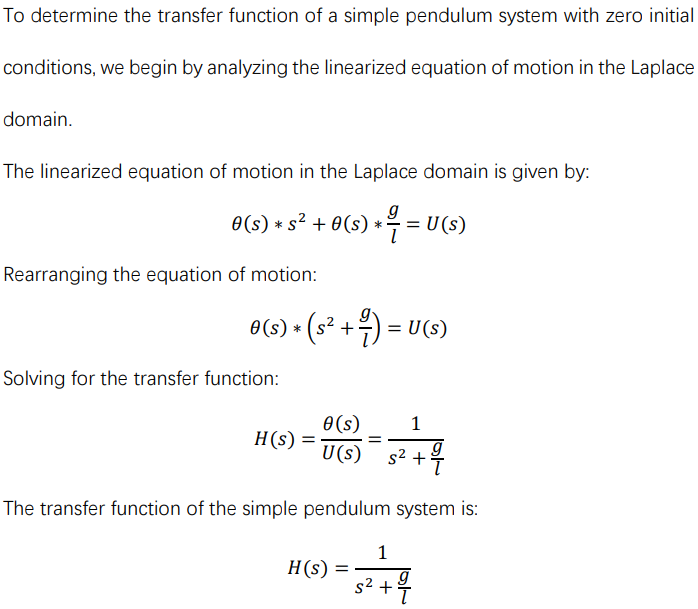

syms g l s 
% Record your answer in pendulumTF

pendulumTF = 1/(s^2+g/l);


checkPendulumTF(pendulumTF) % Checks your answer

Correct!


## Electric vehicle dynamic system

In this module, you'll investigate the dynamics of components of an electric vehicle's electrical and mechanical systems (EV) using transfer functions. The major components of the EV system are represented in the diagram below.

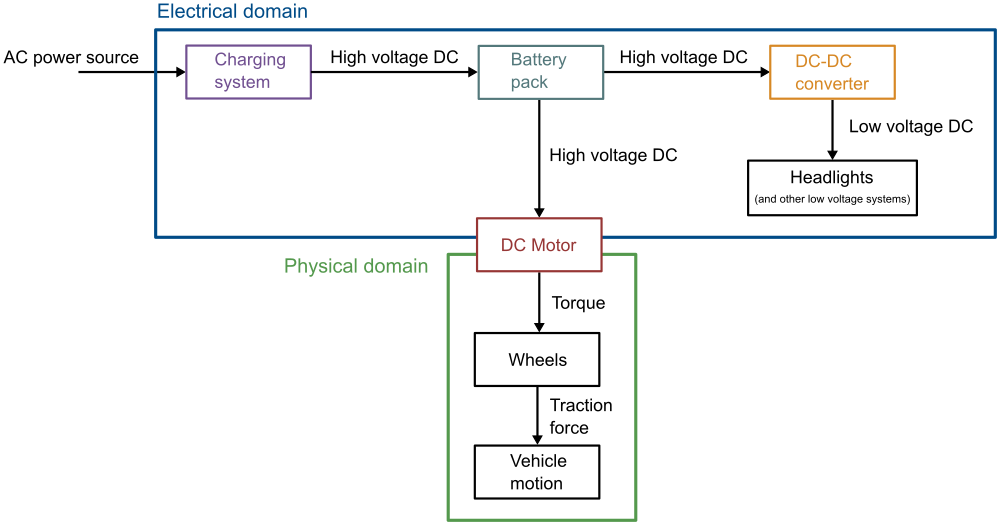

*Simplified EV power system*

There are two domains represented in this diagram: the electrical and physical domains. The DC motor couples the domains by converting electrical energy to mechanical. Inside the electrical domain, there are two essential conversions.

- The AC power source (120/240V) is converted to a high voltage DC source (200-800V) used to charge the battery pack.

- The battery's high voltage DC (200-800V) is converted to a low voltage (12V or 48V) by a buck converter for use by low voltage systems.

In this module, you will investigate several paradigmatic components present (or like those present) in EVs. 

## Transfer function representation of simple vehicle motion

The most intuitive part of the electric vehicle system is the motion of the vehicle itself.

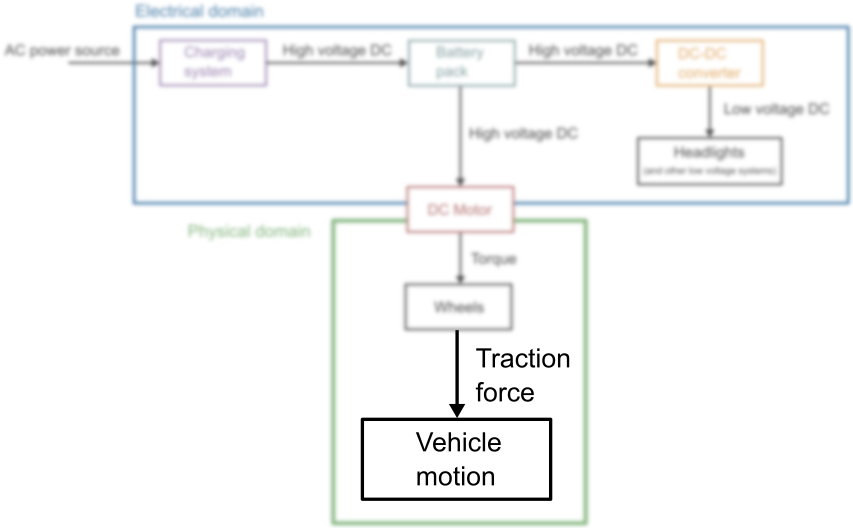

*In this live script, you'll focus on modeling the motion of the vehicle.*

In a straightforward model, an EV (and indeed, any vehicle) can be modeled as a simple mass with two forces acting on it: a traction force and a frictional force. The traction force results from the motor applying torque to the wheels.

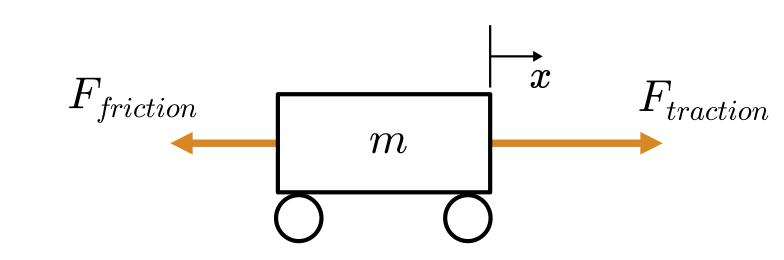

*A simple vehicle model*

** Example. (a) **Derive the equation of motion for the simple vehicle model and **(b) **compute the transfer function of the displacement $x(t)$ using the traction force as the input function $u(t)$.

**Solution. **

**(a) **The displacement of the vehicle is $x(t)$. For simplicity, the frictional force is assumed to be proportional to the velocity $\dot{x}$ with a constant of proportionality $k$:

    
$$F_{friction} = k \dot{x}$$


The traction force varies depending on the output of the motor (among other considerations), so it is treated as an arbitrary function:

    
$$F_{traction} = u(t)$$


With these two forces, Newton's second law implies:

    
$$m\ddot{x} = -k\dot{x}  + u(t)$$


**(b) **Computing the Laplace transform of the equation of motion yields

    
$$m[s^2 X - sx(0) - x'(0)] = - k [s X - x(0)] + U$$


Applying the zero initial conditions and solving for $X/U$ yields

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ms^2 + ks}$$


There are many simplifications present in this vehicle model (especially in the way the frictional forces are modeled). The model is intended to help illustrate the essential concepts of transfer functions, rather than accurately account for the forces present in the true mechanical system.

** Exercise 2. **It may be the case that you want to analyze the velocity $v(t)$ rather than the position $x$. Rewrite the equation of motion 

    
$$m\ddot{x} = -k\dot{x}  + f(t)$$


in terms of the velocity, $v(t) = \dot{x}(t)$, and then solve for the transfer function of $v$: $H(s) = V(s)/F(s)$. Record your answer below in `Vtf` in terms of the symbolic variables `s`, `m`, and `k`, and then run the section to check your result.

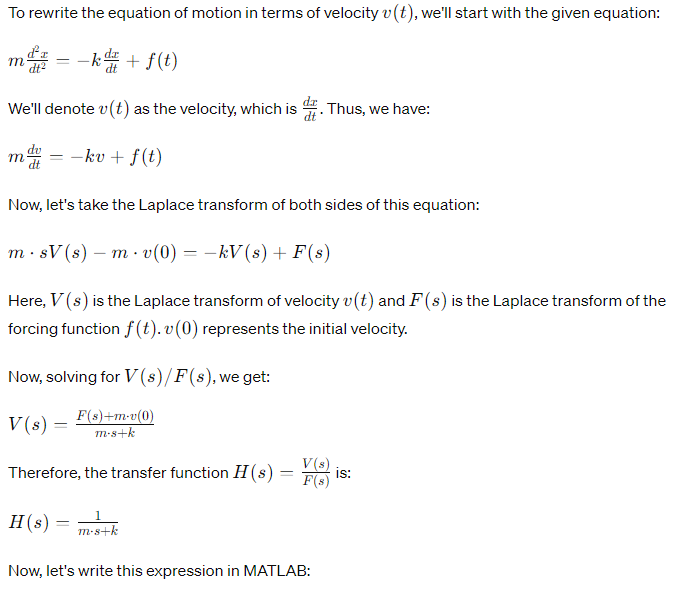

syms m s k % Symbolic variable declarations
% Record your answer here

Vtf = 1/(m*s+k);

checkVTF(Vtf) % Checks your answer

Correct!


## Impulse response 

The impulse response of a system is the output generated from an impulse input. This is also commonly referred to as the natural response.

       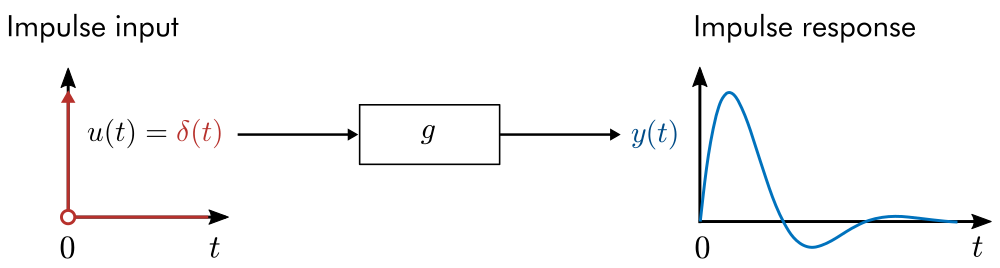

*        Response of a system to an impulse. While the response may be computed in the *$s$*-domain, it is shown in the time domain.*

Here $\delta(t)$ is the Dirac delta function which has the properties:

    $\int_{-\infty}^{\infty} \delta(t) dt = 1 $   and   $\delta(t) = 0 \text{ for } t \neq 0$

Think of the unit impulse as giving the system a (very) quick shove at time $t=0$. The impulse response shows how the system will respond to that shove.

** Exercise 3. **

 Consider the simple vehicle motion model. The input function is the traction force $u(t) = F_{traction}(t)$. An impulse input corresponds to an instantaneous force at time $t=0$.

        

- Try drawing a plot of the impulse response of the position transfer function $X(s)/F(s)$ in the time domain.

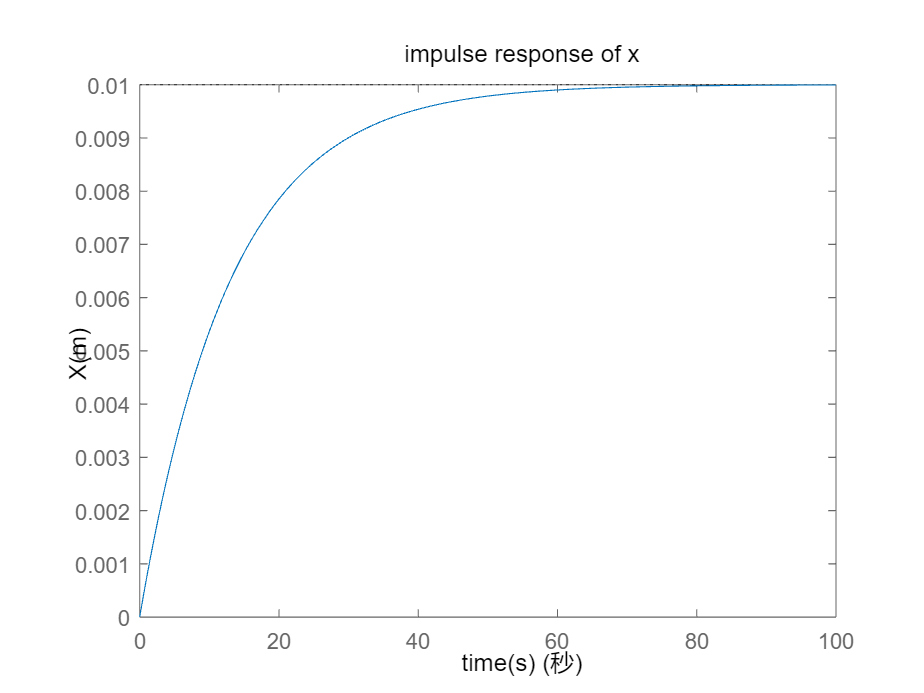

% Define symbolic variables and Laplace domain
syms s t

% Define system parameters
m = 1300;   % Mass (kg)
k = 100;    % Frictional constant (Ns/m)

x_t = 1/k*(1-exp(-k/m*t));

% Define the transfer function
G = 1/(m*s^2+k*s);

% Compute the impulse response in the time domain
num_x = 1;
den_x = [m k 0];
H = tf(num_x, den_x);

% Plot the impulse response
t = 0:0.1:100;
impulse(H, t);
title('impulse response of x')
xlabel('time(s)')
ylabel('X(m)')

- Try drawing a plot of the impulse response of the velocity transfer function $V(s)/F(s)$ in the time domain.

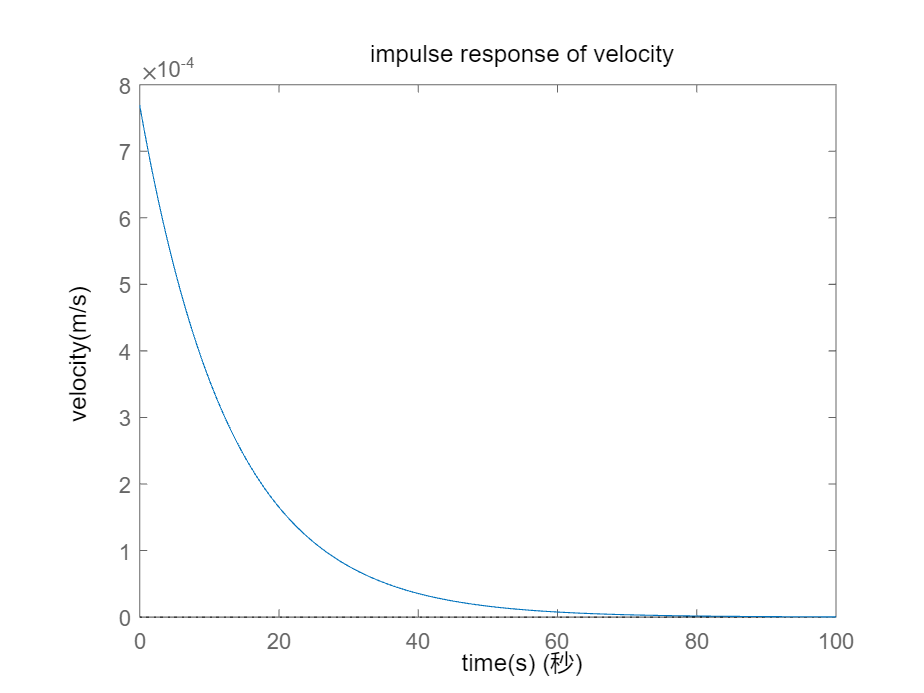

% Define symbolic variables and Laplace domain
syms s t

% Define system parameters
m = 1300;   % Mass (kg)
k = 100;    % Frictional constant (Ns/m)

% Define the velocity transfer function

Vtf = 1/(m*s+k);



% Compute the impulse response in the time domain

v_t = 1/m*exp(-k/m*t);

% Plot the impulse response

% Define the transfer function
G = 1/(m*s+k);

% Compute the impulse response in the time domain
x_t = ilaplace(G, s, t);
num_x = 1;
den_x = [m k];
H = tf(num_x, den_x);

% Plot the impulse response
t = 0:0.1:100;
impulse(H, t);
title('impulse response of velocity')
xlabel('time(s)')
ylabel('velocity(m/s)')

** Example 2. **Plot the impulse response of a mass-spring-damper with zero initial conditions and parameters $m = 1$, $c = 0.1$, and $k = 0.5$. 

      

        *Mass-spring-damper diagram*

Recall the transfer function of the mass-spring-damper:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{m s^2 + cs + k}$$


**Solution.**

You can compute the impulse response in MATLAB by defining a transfer function using [`tf`](https://www.mathworks.com/help/control/ref/tf.html) and then evaluating its response using the [`impulse`](https://www.mathworks.com/help/control/ref/lti.impulse.html) function.

The `tf `function has the syntax

     `tf(num,denom)`

where `num` represents the coefficients of the numerator and `denom` represents those of the denominator in descending order. Note that a transfer function created using the `tf` function is not a symbolic function and cannot be manipulated with the Symbolic Math Toolbox.

The numerator and denominator of $G$ are defined below.

m = 1; % Default: 1
c = 0.1; % Default: 0.1
k = 0.5; % Default: 0.4
num = [0 0 1];
denom = [m c k];

Call `tf` to build the transfer function.

G = tf(num,denom);

To plot the impulse response, call the `impulse` function with the syntax:

where `H` is the transfer function and `tFinal` is the duration of the simulation.

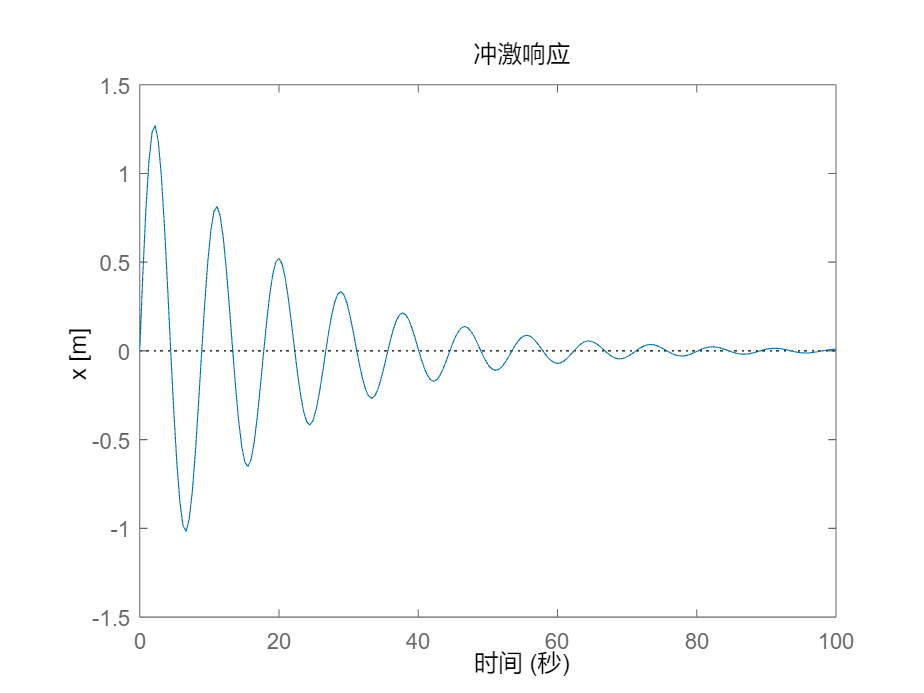

impulse(G,100);
ylabel("x [m]")

- How are the damping $c$ and spring stiffness $k$ reflected in the impulse response?

                The impulse response of the system is **underdamped**：$\zeta = \frac{c}{2\sqrt{mk}} \approx 0.0707< 1$

                The spring stiffness **k** primarily affects the system's response speed and oscillation frequency.

                The damping coefficient **c** primarily influences the rate of oscillation decay and whether the system oscillates.

- If $c$ is increased to 0.5, how will the response change?

                $\zeta = \frac{c}{2\sqrt{mk}} \approx 0.3536< 1$ so the system remains **underdamped**.

- Try setting $c = 0.5$ and recompute the impulse response.

                $G(s) = \frac{1}{s^2 + 0.5s + 0.5}$, $\zeta = \frac{c}{2\sqrt{mk}} \approx 0.3536< 1$, $\[
g(t) \approx \frac{1}{1 \times 0.6614} e^{-0.25 t} \sin(0.6614 t) \approx 1.512 e^{-0.25 t} \sin(0.6614 t)
\]$

- Try setting $k = 1$ and recompute the impulse response.

               $\zeta = \frac{c}{2\sqrt{mk}} = 0.05 <1$, $\[
g(t) \approx \frac{1}{1 \times 0.9987} e^{-0.05 t} \sin(0.9987 t) \approx 1.0013 e^{-0.05 t} \sin(0.9987 t)
\]$

** Exercise. **Consider a simple vehicle with a mass of 1300 kg and a frictional constant of proportionality of $k = 100$ N$\cdot$s/m. Recall that the simple vehicle motion model has a transfer function:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ms^2 + ks}$$


Plot the impulse response of $G$ for the first 100 seconds using MATLAB commands by

- creating the transfer function using the `tf` function

- plotting the impulse response using `impulse` function

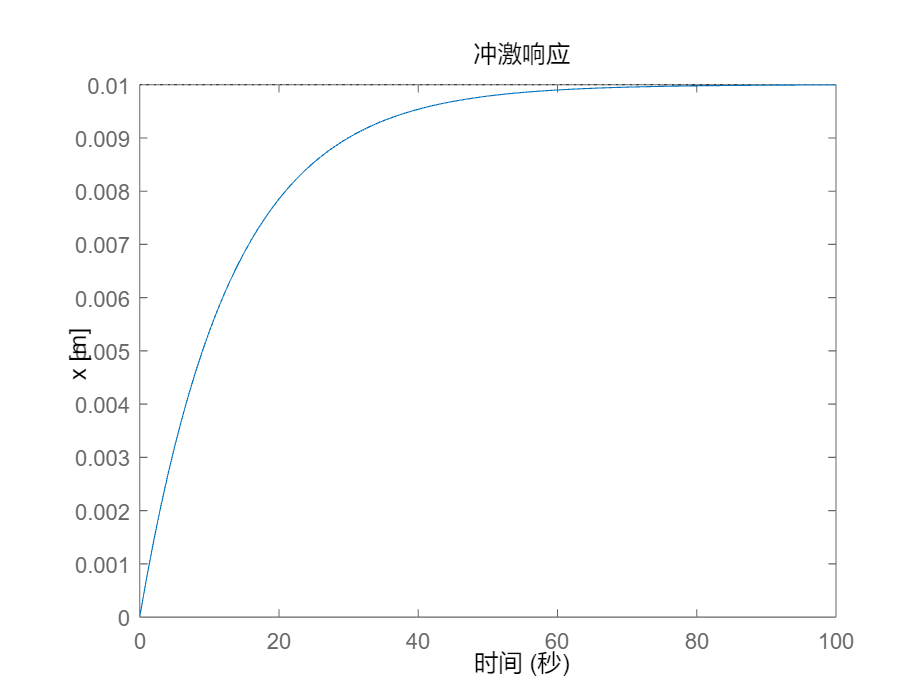

% Define system parameters
m = 1300; % Mass (kg)
k = 100; % Frictional constant (Ns/m)

% Define the transfer function

num=[0 0 1];
den= [m k 0];
G = tf(num,den);

% Plot the impulse response for the first 100 seconds
impulse(G,100);
ylabel("x [m]")

This MATLAB code creates the transfer function G(s)  using the `tf` function with the given numerator and denominator coefficients. Then, it plots the impulse response of the system using the `impulse` function over the first 100 seconds.

- How does the impulse response compare to your prediction for the impulse response?

               Roughly the same as my prediction:The impulse response *g*(*t*) is a gradually increasing curve that eventually settles to a steady-state value of 1/100�.The response speed of the system is determined by the time constant τ=13 s, *τ*=13s.By adjusting m*m* and *k*, the dynamic response characteristics of the system can be modified.

- Physically, what does the long-term behavior of the impulse response represent?

                The result of response tends to be 1 with damping.

- Define the velocity transfer function $H(s) = \frac{1}{ms  + k}$ and compute the impulse response in the space below. Physically, what does the limiting behavior represent?

                The limiting behavior represents the system's return to equilibrium after the initial disturbance, with the rate of decay governed by the damping coefficient *k* and mass *m*.

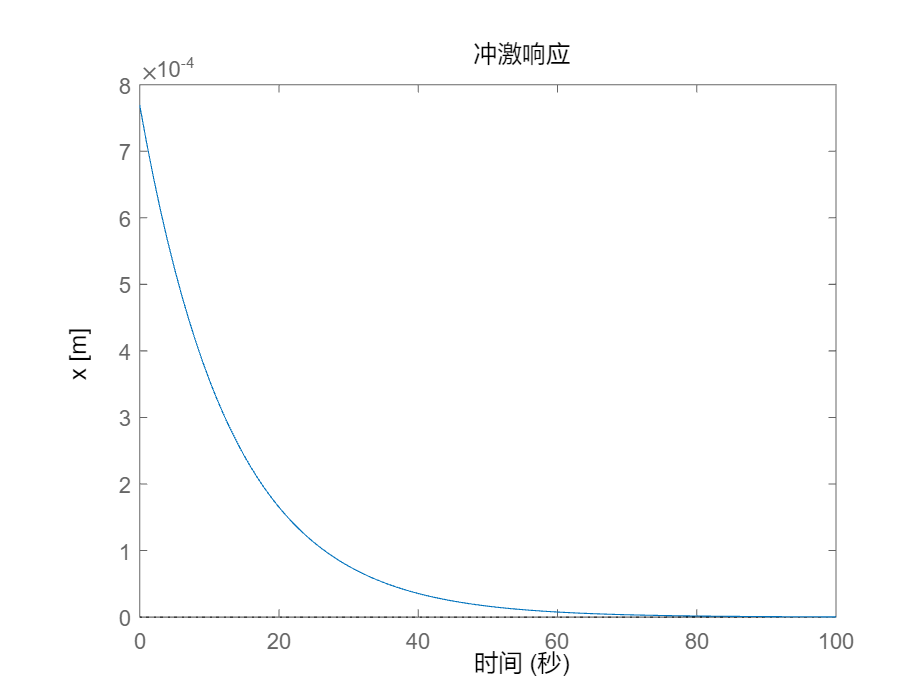

% Define system parameters
m = 1300; % Mass (kg)
k = 100; % Frictional constant (Ns/m)

% Define the velocity transfer function

num=[0 1];
den= [m k];
G = tf(num,den);

% Plot the impulse response for the first 100 seconds
impulse(G,100);
ylabel("x [m]")

## Step response

The output generated from a step input is known as the step response.

    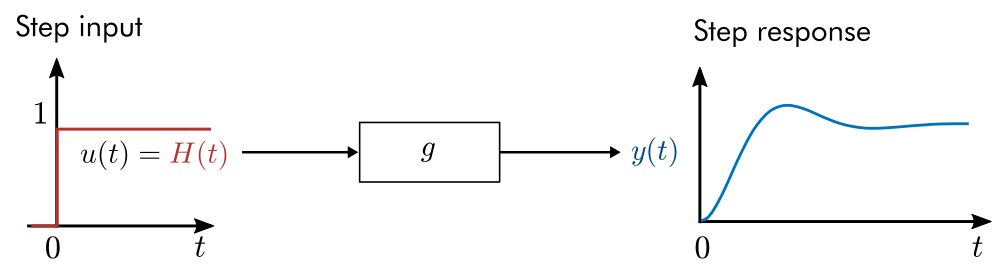

*       Response of a system to a step input.*

The step response is plotted in the time domain. Think of the step response as the system's response to a sustained constant forcing. In the vehicle model, this would result from continuously running the motor (with the assumption that it produced a constant traction force output).

**  Reflect.** Consider the simple vehicle motion model. The input function is the traction force $u(t) = F_{traction}(t)$.

        

- Try drawing a plot of the step response of the position transfer function $G(s) = X(s)/F(s)$ in the time domain.

- Try drawing a plot of the step response of the velocity transfer function $H(s) = V(s)/F(s)$ in the time domain.

** Exercise. **Consider a simple vehicle with a mass of 1300 kg and a frictional constant of proportionality of $k = 100$ N$\cdot$s/m. Recall that the simple vehicle motion model has a transfer function:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ms^2 + ks}$$


Define the transfer function `G` in MATLAB using the `tf` function and then plot the step response for the first 30 seconds using the `step` function. The step function has the syntax

`    step(sys,Tfinal)`

where `sys` is a dynamic system (here, that's the transfer function `G`) and `Tfinal` is the time to stop the simulation.

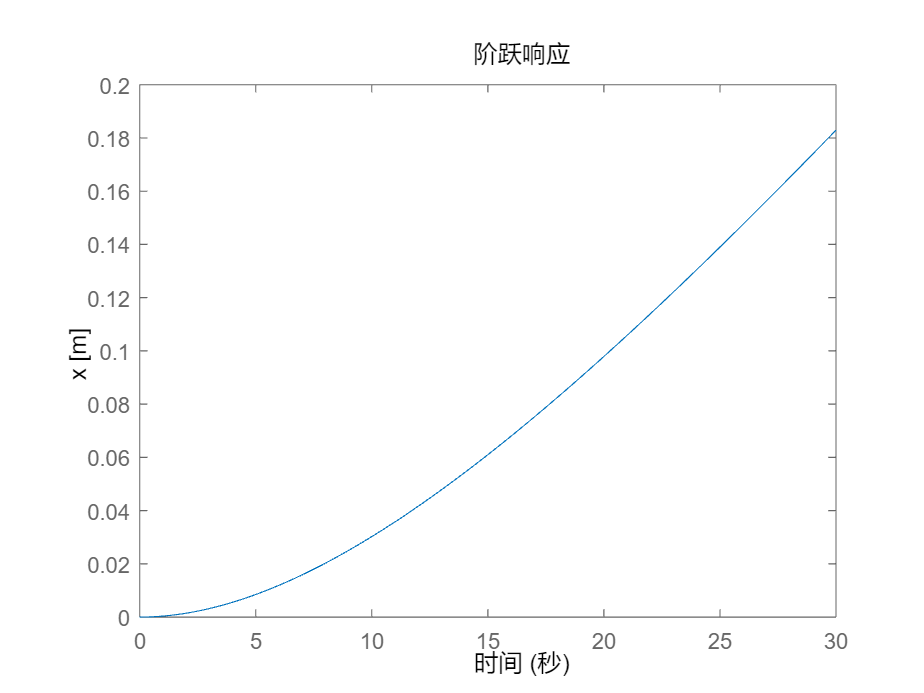

% Define system parameters
m = 1300; % Mass (kg)
k = 100; % Frictional constant (Ns/m)

% Define the transfer function
num=[0 0 1];
den= [m k 0];
G = tf(num,den);


% Plot the step response for the first 30 seconds
step(G,30);
ylabel("x [m]")

- How does the step response compare to your prediction?

                Roughly the same as my prediction:The plot will help visualize how quickly and smoothly the system reaches its steady-state position in response to a step input.

- What physical action does the initial transient behavior reflect?

                This behavior is typical of a second-order system with damping, where the initial transient phase shows how the system transitions from one state to another in response to an external disturbance.

- What does the long-term behavior of the step response reflect?

                Approaching a straight line.

** Exercise. **Consider the same simple vehicle with a mass of 1300 kg and a frictional constant of proportionality of $k = 100$ N$\cdot$s/m. This time, however, analyze the vehicle's velocity $v(t)$ instead of its position $x(t)$. Recall that the velocity transfer function is

    
$$H(s) = \frac{1}{ms  + k}$$


Compute the step response of the velocity transfer function and use it to determine the vehicle's maximum velocity undergoing a unit step forcing.

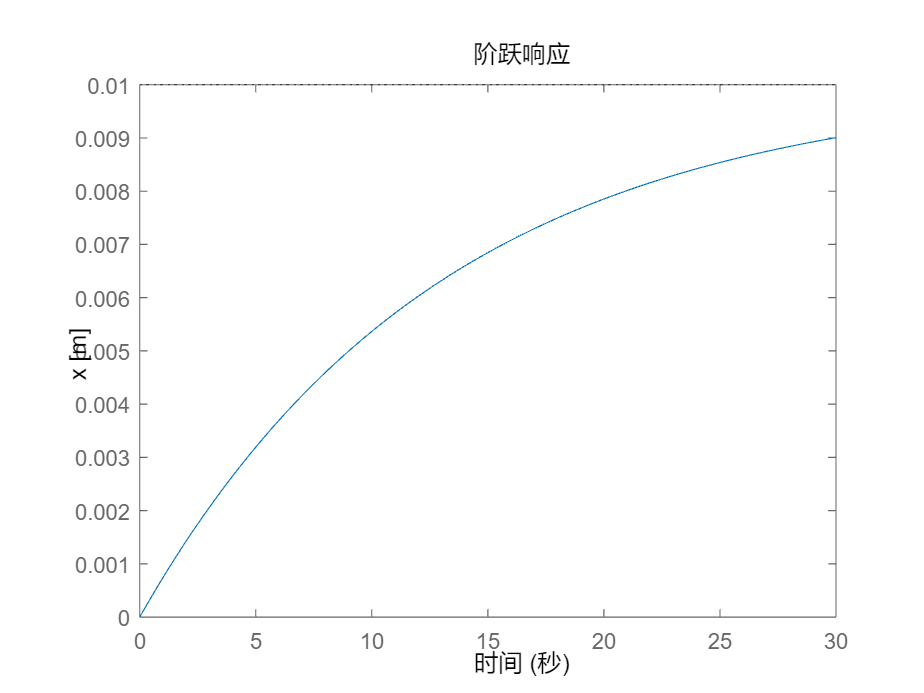

% Define system parameters
m = 1300; % Mass (kg)
k = 100; % Frictional constant (Ns/m)

% Define the transfer function
num=[0 1];
den= [m k];
G = tf(num,den);


% Plot the step response for the first 30 seconds
step(G,30);
ylabel("x [m]")


% Find the maximum velocity
[max_velocity, t_max] = max(step(G, 30));

% Display the maximum velocity
disp(['Maximum velocity: ', num2str(max_velocity), ' m/s']);

Maximum velocity: 0.0090051 m/s


- As you probably noticed, the vehicle's maximum speed under the unit step forcing is only 0.01 m/s, which is about 0.022 mph. That happens because the unit step only applies a traction force of 1 N, which is not nearly enough for a 1300 kg vehicle. 

- To create a more realistic response, you can add gain to the system by multiplying the transfer function by a constant and then recomputing the step response. What value of the gain constant will produce a maximum speed of 50 m/s (or 112 mph)?

- Compute the step response of `H*gain` in the space below, where `gain` is the gain constant that will produce a maximum velocity of 50m/s. 

- How long does it take for the vehicle to accelerate from 0 to 60 mph (0 to 26.8m/s)?

% Define system parameters
m = 1300; % Mass (kg)
k = 100;  % Frictional constant (Ns/m)

% Define the desired maximum velocity
desired_max_velocity = 50; % m/s

% Compute the gain constant
K = desired_max_velocity * k;

% Define the adjusted velocity transfer function with gain
num = [0 1];
den = [m k];
G = tf(num, den);
G_new = K * G;

% Compute the step response
[response, time] = step(G_new, 30);

% Find the time to accelerate from 0 to 60 mph
% Convert 60 mph to m/s
desired_speed_mps = 60 * 0.44704; % m/s

% Find the time when the velocity first exceeds desired speed
time_to_desired_speed = time(find(response >= desired_speed_mps, 1));

% Display the gain constant and time to accelerate
disp(['Gain constant K: ', num2str(K)]);

Gain constant K: 5000


disp(['Time to accelerate from 0 to 60 mph: ', num2str(time_to_desired_speed), ' seconds']);

Time to accelerate from 0 to 60 mph: 10.2 seconds


In this code:

- We compute the gain constant needed to achieve the desired maximum velocity of 50 m/s by dividing it by the current maximum velocity.

- We define the adjusted velocity transfer function with the computed gain constant.

- We compute the step response of the adjusted system.

- Finally, we find the time it takes for the vehicle to accelerate from 0 to 60 mph by finding the time when the velocity first exceeds 60 mph.

## Analytic computation of the impulse and step responses

At this point, you may have wondered: how are the impulse and step responses calculated? In MATLAB, they are numerically estimated. In many common cases, it is also possible to derive the response analytically. While in practice solving for the analytic response is typically unnecessary, it is a valuable exercise to develop further intuition.

To analytically solve for the impulse or step response:

- take the Laplace transform of the input function

- solve for $X(s)$

- back-transform $X(s)$ to obtain the time-domain response $x(t)$

If you don't want to perform Step 1 by hand, you can simply use a table or the `laplace` function. You can complete Step 3 using a transform table or the [`ilaplace`](https://www.mathworks.com/help/symbolic/ilaplace.html) function from the Symbolic Math Toolbox.

 **Example. **

**(a) **Compute the analytic impulse response for the simple vehicle model using its position transfer function.

**(b)** Set $m = 1300$ and $k = 100$. Then plot the analytic impulse result and compare it to the solution found using the `impulse` function.

**Solution. **

**(a) **Recall that the position transfer function for the simple vehicle model was:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ms^2 + ks}$$


Start by computing the Laplace transform of the input forcing function $\delta(t)$:

    
$$U(s) = \int_{0}^\infty \delta(t) e^{-st} dt = e^{-st}|_{t = 0} = 1$$


This implies that

    
$$X(s)= \frac{1}{ms^2 + ks}$$


At this point, you can refer to a table or use the `ilaplace` function to evaluate the inverse Laplace transform.

syms m k positive
syms s x
X = 1/(m*s^2+k*s);
x = ilaplace(X, s, t);

**(b) **First define the transfer function using `tf` and then compute the impulse response.

m = 1300;
k = 100;
num=[0 0 1];
den= [m k 0];
Xs = tf(num,den);
[x,t] = impulse(Xs);

Now compute the analytic solution on the same interval and plot the comparison.

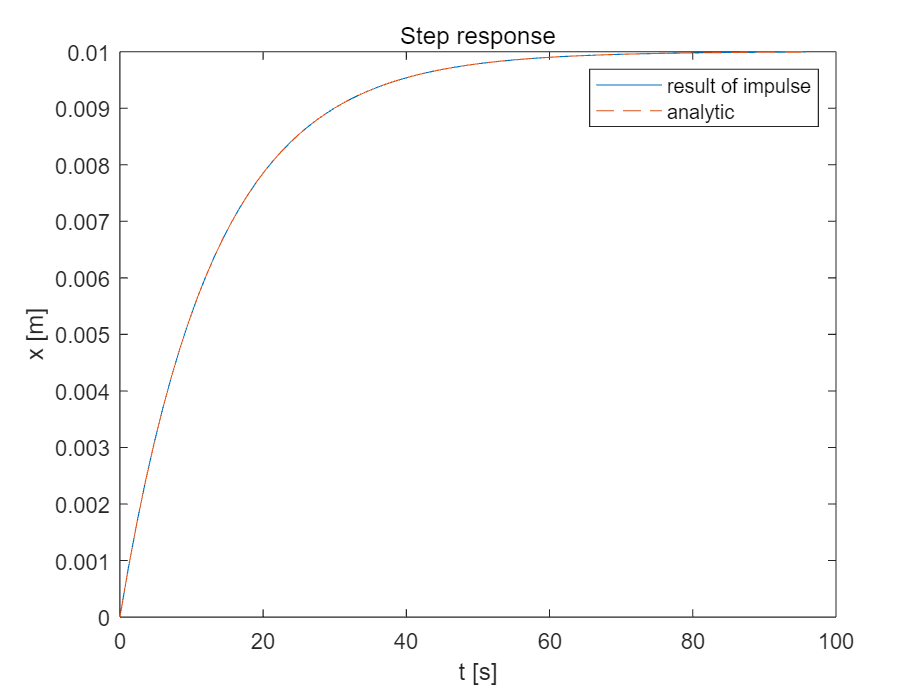

xAnalytic = 1/k - exp(-k*t/m)/k;
plot(t,x,t,xAnalytic,'--')
legend("result of impulse", "analytic")
xlabel("t [s]")
ylabel("x [m]")
title("Step response")

 **Exercise. **

**(a) **Compute the analytic **step** response for the vehicle position transfer function. Recall that the position transfer function for this simple vehicle model was:

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ms^2 + ks}$$


Store the output in symbolic variable x using the pre-defined symbolic variables.

% Use these symbolic variables
syms m k real
syms s x t

% Compute the symbolic form of the step response and store it in x
 G = 1 / (m * s^2 + k * s);
 Us = 1 / s;
 X = G * Us;
 x = ilaplace(X, s, t);
checkAnalyticStep(x)

Correct!


**(b)** Set $m = 1300$ and $k = 100$. Then plot the analytic step result you computed in **(a)**. Also, plot the step response calculated using the `step` function.

% Define constants
m_val = 1300;
k_val = 100;

% Time array
t = linspace(0, 20, 1000);

% Compute analytic solution
xAnalytic = (1 / k_val) * (1 - exp(-(k_val / m_val) * t));

% Define transfer function using tf
Xs = tf([0 0 1], [m_val, k_val, 0]);



Evaluate your analytic solution here in terms of the array `t` using the constant values of `k` and `m`. Plot the result together with the output of the `step` function.

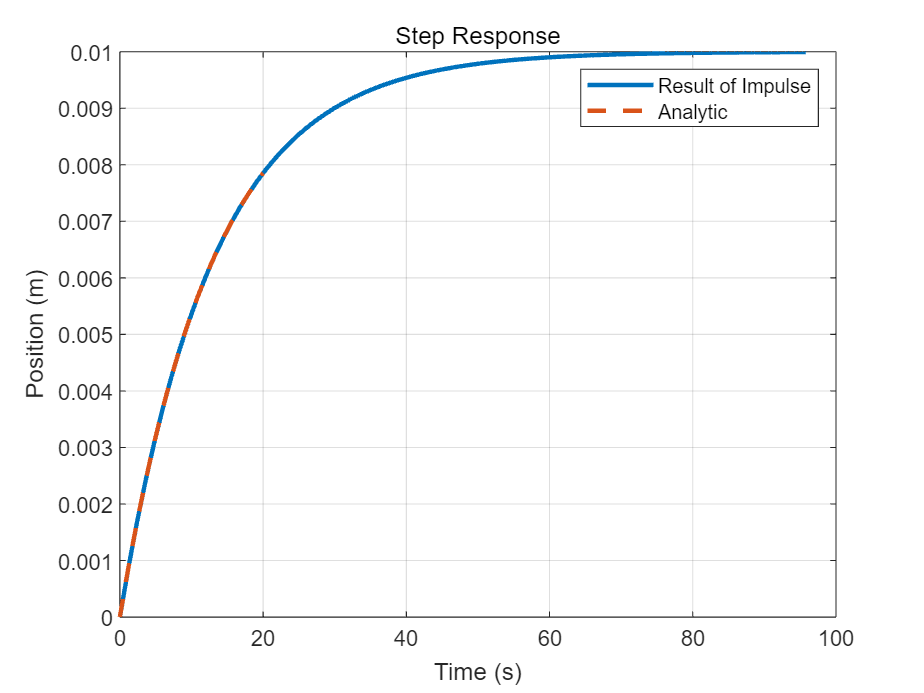

% Compute impulse response
[x_impulse, t_impulse] = impulse(Xs);

% Plot the results
plot(t_impulse, x_impulse, t, xAnalytic, '--', 'LineWidth', 2);
legend('Result of Impulse', 'Analytic');
xlabel('Time (s)');
ylabel('Position (m)');
title('Step Response');
grid on;

This code first defines the symbolic transfer function *X* and computes its inverse Laplace transform. Then it defines the constants *m* and *k*, creates the analytic solution, and defines the transfer function using `tf`. After computing the impulse response, it plots both results together for comparison.

## Forced response

It is also possible to compute the response of a system to an arbitrary input function $u(t)$. 

        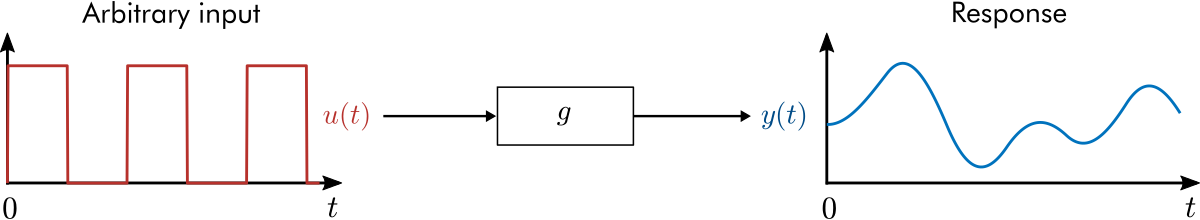

        *Response of a system to a square wave.*

Analytically, this can be accomplished by computing $U(s)$ and subsequently finding the inverse Laplace transform of $X(s)$. In cases where the analytic expression does not exist, you can estimate the response numerically using the [`lsim`](https://www.mathworks.com/help/control/ref/lti.lsim.html) function.

  **Activity.**

    In this activity, you will analyze the response of the mass-spring-damper system

        
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{m s^2 + cs + k}$$


    The mass-spring-damper is assumed to start at rest and is driven by an input function $u(t)$.

**Part 1.** Familiarize yourself with the activity.

- Adjust the input function `u` using the dropdown and observe the responses.

- Adjust the mass-spring-damper parameters and the input frequency to observe the changes to the response.

- Check the "animate" box to show an animation of the mass-spring-damper. You can turn this on or off during the remainder of the activity as you prefer.

**Part 2. **Find the resonant frequency.

- It is a well-known phenomenon that systems will become unstable if they are driven at their resonant frequency. Try extending the simulation time by increasing `tfinal`. Is the system being driven at the resonant frequency?

- You should notice that the transient response is characterized by two frequencies: the driving frequency and the mass-spring-damper's natural frequency. Is the natural frequency of the oscillator larger or smaller than the driving (input) frequency?

- Adjust the input frequency so that it matches the natural frequency of the mass-spring-damper. Do you observe resonant oscillations?

- Set the damping to zero. If you are at (or very close to) the resonant frequency, you should observe that the response will grow without bound.

- Try driving the oscillator with a different input function. Does the function choice affect the resonant oscillations?

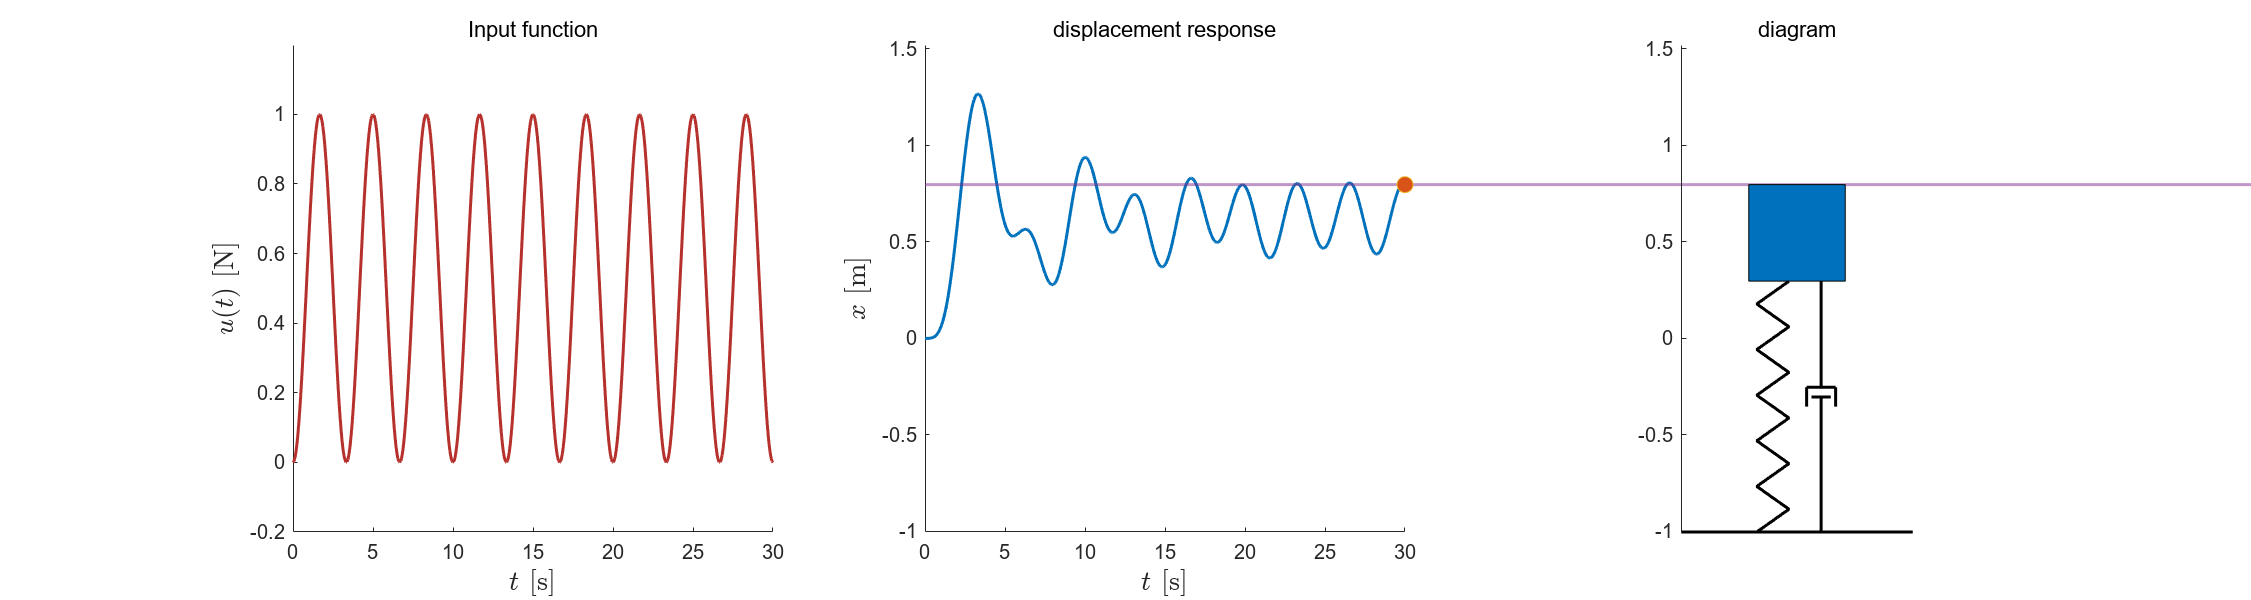

m = 1; % Default: 1
c = 0.3; % Default: 0.1
k = 0.8; % Default: 1
freq = 0.15; % Frequency in Hz. Default: 0.25
tfinal = 30; % Simulation duration. Default: 30
t = linspace(0,tfinal,500);
u = sin(2*pi*freq*t).^2;
animate = true;
 

% Compute and plot the response
G = tf([0 0 1],[m c k]); % The transfer function
[x,t] = lsim(G,u,t); % Simulate the response using lsim
if(~animate)
    plotResponse(t,u,x) % regular plot

subplot(1,2,2)
xlim([0.4 27.7])
ylim([0.14 1.40])
else 
    animateSingleMSD(t,x,u,0.5,200) % animated response
end

 **Exercise. **In this exercise, you will compute the analytic response of the mass-spring-damper to a sine wave input function and compare the result to the numerical values computed by `lsim`. For this exercise, assume the mass-spring-damper parameters are $m = 1$, $c = 0$, and $k = 1$. The transfer function is therefore

        
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{s^2 + 1}$$


You can perform your analytic computations by hand or in MATLAB using the Symbolic Math Toolbox. When using symbolic math, make sure to declare your symbolic variables before using them. For example:

**(a) **Compute the Laplace transform of the input function:

     
$$u(t) = \sin(2\pi f t)$$


where $f$ is a constant (the frequency in Hz). 

% Declare symbolic variables
syms f t s

% Define the input function
u = sin(2*pi*f*t);

% Compute the Laplace transform of the input function
U = laplace(u,t,s);
disp('Laplace transform of the input U(s):');

Laplace transform of the input U(s):


disp(U);

$$\frac{2\,\pi \,f}{4\,\pi^{2}\,f^{2}+s^{2}}$$

In this code:

- We declare symbolic variables f t s.

- We define the input function    $u(t) = \sin(2\pi f t)$

- We compute the Laplace transform of the input function using the `laplace` function in MATLAB, which takes the input function, the time variable *t*, and the Laplace variable *s* as arguments.

**(b)**  Find the expression for the response in the Laplace domain: X(s).

% Define the transfer function G(s)
G = 1 / (s^2 + 1);

% Compute the response in Laplace domain X(s)
X = G * U;

% Display the expression for X(s)
disp('The expression for the response in the Laplace domain X(s) is:');

The expression for the response in the Laplace domain X(s) is:


disp(X);

$$\frac{2\,\pi \,f}{\left(4\,\pi^{2}\,f^{2}+s^{2}\right)\,\left(s^{2}+1\right)}$$

**(c) **Compute the inverse Laplace transform of $X(s)$ to identify the time-domain response $x(t)$.

% Display the expression for X(s)
disp('The expression for the response in the Laplace domain X(s) is:');

The expression for the response in the Laplace domain X(s) is:


disp(X);

$$\frac{2\,\pi \,f}{\left(4\,\pi^{2}\,f^{2}+s^{2}\right)\,\left(s^{2}+1\right)}$$


% Compute the inverse Laplace transform of X(s) to get x(t)
x = ilaplace(X, s, t);

% Display the expression for x(t)
disp('The expression for the time-domain response x(t) is:');

The expression for the time-domain response x(t) is:


disp(x);

$$\frac{2\,\pi \,f\,\sin\left(t\right)}{\left(2\,\pi \,f-1\right)\,\left(2\,\pi \,f+1\right)}-\frac{\sin\left(2\,\pi \,f\,t\right)}{\left(2\,\pi \,f-1\right)\,\left(2\,\pi \,f+1\right)}$$

**(d)** Evaluate the analytic response for $f = 0.16$ on the interval $[0,50]$ and plot it.

**Hint: **If you computed $x$ symbolically in MATLAB, you can convert it to a function handle using [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) and evaluate that instead of writing out the expression yourself. For example:

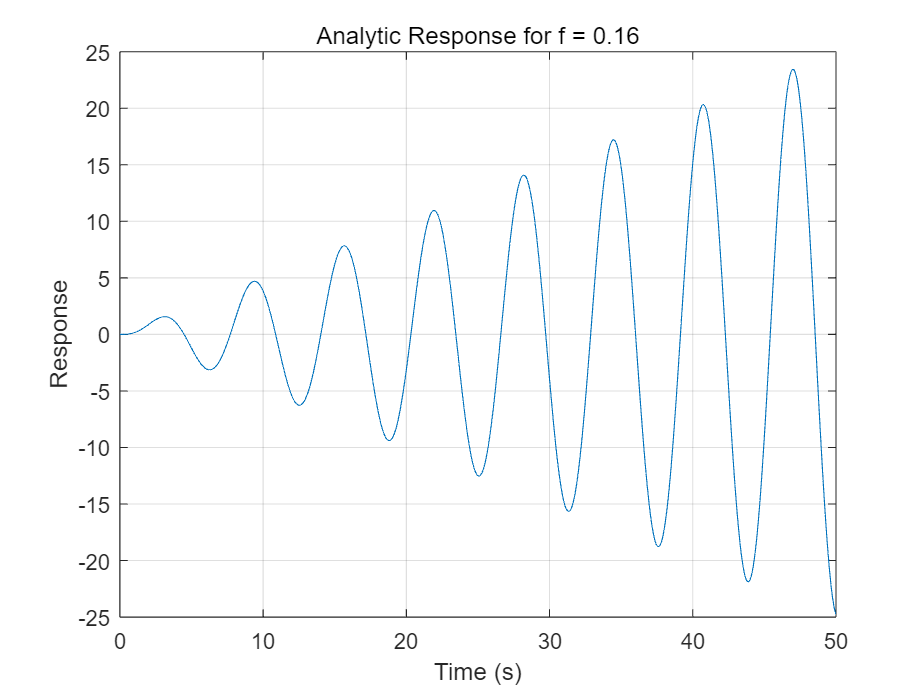

% Convert the symbolic expression to a function handle
xfunc = matlabFunction(x);

% Define the frequency
freq = 0.16;

% Evaluate the analytic response for f = 0.16 on the interval [0, 50]
t_values = linspace(0, 50, 1000);
x_values = xfunc(freq, t_values);

% Plot the analytic response
plot(t_values, x_values);
xlabel('Time (s)');
ylabel('Response');
title('Analytic Response for f = 0.16');
grid on;

**(e) **Use the [`lsim`](https://www.mathworks.com/help/control/ref/lti.lsim.html) function to compute the same response and plot it together with the analytic response.

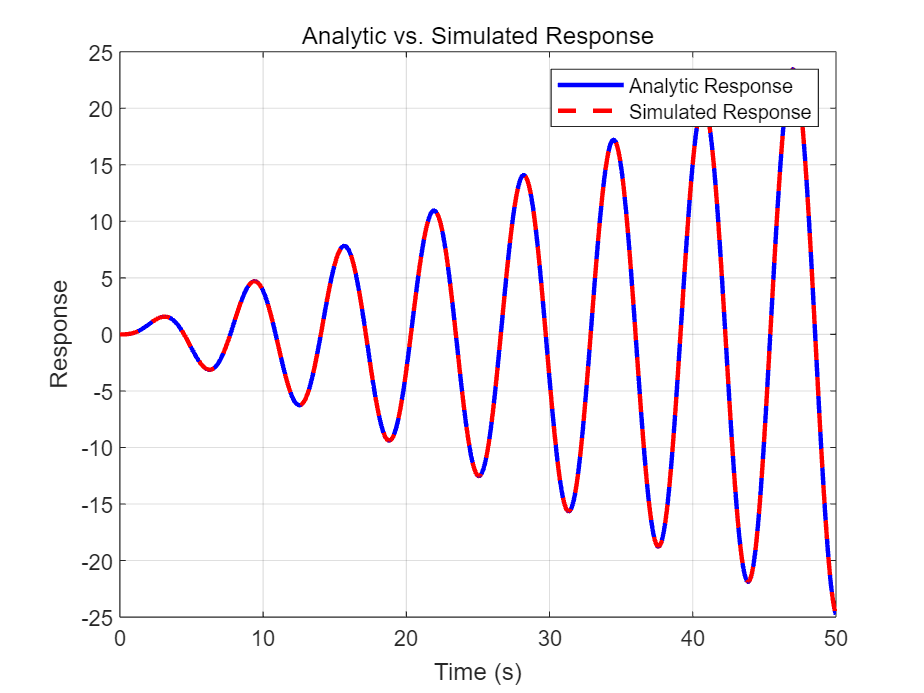

% Declare symbolic variables
syms f t s

% Define the input function
u = sin(2*pi*f*t);
U = laplace(u, t, s);
G = 1 / (s^2 + 1);
X = G * U;
x = ilaplace(X, s, t);
xfunc = matlabFunction(x);

% Define the frequency
freq = 0.16;

% Evaluate the analytic response for f = 0.16 on the interval [0, 50]
t_values = linspace(0, 50, 1000);
x_values = xfunc(freq, t_values);

% Define the input signal for simulation
u_sim = sin(2*pi*freq*t_values);

% Define the transfer function as a tf object for lsim
G_tf = tf(1, [1 0 1]);

% Compute the simulated response using lsim
x_sim = lsim(G_tf, u_sim, t_values);

% Plot the analytic and simulated responses
plot(t_values, x_values, 'b', 'LineWidth', 2);
hold on;
plot(t_values, x_sim, 'r--', 'LineWidth', 2);
hold off;
xlabel('Time (s)');
ylabel('Response');
title('Analytic vs. Simulated Response');
legend('Analytic Response', 'Simulated Response');
grid on;

**Helper functions**

**Plots**

function plotResponse(t,u,x)
% This function generates a response plot
    figure("position",[0 0 1000 300])
    
    subplot(1,2,1)
    plot(t,u,"color",[0.7176 0.1922 0.1725],"linewidth",1.5)
    xlabel("t")
    ylabel("u(t)")
    box off
    axis([t(1),t(end),min(u)-0.2,max(u)+0.2])
    title("Input function")
    
    subplot(1,2,2)
    plot(t,x,"linewidth",1.5,"color",[0 0.4470 0.7410])
    xlabel("t")
    ylabel("x(t)")
    xlim([t(1) t(end)])
    title("Response")
    box off
end


function animateSingleMSD(tin,xin,uin,w,Npoints)
% Generates an animation of a single mass/spring/damper
% t: time array
% x: displacement array
% w: width of the mass

    % Interpolate to Npoints
    t = linspace(tin(1),tin(end),Npoints);
    x = interp1(tin,xin,t);
    u = interp1(tin,uin,t);

    colors = lines(6); 
    fs = 14;
    
    % Create plot
    k = 1;
    figure("position",[0 0 1500 400]);
    
    % Setup the figure
    buffer = 1.2;
    xrange = max(x) - min(x);
    xmax = min(x) + xrange*buffer ;
    xmin = max(x) - xrange*buffer - w*1.5;
    tlim = [t(1) t(end)];
    axisLim1 = [tlim(1),tlim(2),xmin,xmax];
    axisLim2 = [-w*buffer,w*buffer,xmin,xmax];
    xground = xmin;
    
    subplot(1,3,1);
    plot(tin,uin,"color",[0.7176 0.1922 0.1725],"linewidth",1.5)
    xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
    ylabel("$u(t)$ [N]","Interpreter","latex","FontSize",fs)
    box off
    axis([t(1),t(end),min(u)-0.2,max(u)+0.2])
    title("Input function")
    
    subplot(1,3,2);
    set(gca, "Clipping","off","Color","none"); 
    hold on
    plot(tin,xin,"k-","color",colors(1,:),"linewidth",1.5);
    a = plot([0, tlim(2)+(tlim(2)-tlim(1))*4], [x(k),x(k)],"-","color",[colors(4,:),0.5],"linewidth",1.5);
    b = plot(t(k),x(k),"o","markerfacecolor",colors(2,:),"MarkerSize",8);
    hold off
    axis(axisLim1)
    box off
    xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
    ylabel("$x$ [m]","Interpreter","latex","FontSize",fs)
    title("displacement response")
        
    subplot(1,3,3);
    set(gca, "Clipping","off","Color","none");
    hold on
    plot([-w*buffer w*buffer],[xground xground],'k-',"linewidth",1.5);
    % Plot mass
    x1 = x(k) - w/2;
    c = rectangle("Position",[-w/2 x1-w w w],"FaceColor",colors(1,:));
    % Plot spring
    xextension = x(k)-w;       
    xs = linspace(xground,xextension,12);
    ys = w/6*(-1).^(1:numel(xs)) - w/4;
    d = plot(ys,xs,"k","linewidth",1.5);
    % Plot damper
    ydamp = w/4;
    xdamp1 = xground + (xextension-xground)/2 + w*0.1;
    xdamp2 = xground + (xextension-xground)/2;
    xdamp3 = xground + (xextension-xground)/2 + w*0.2;
    e = plot([ydamp,ydamp,NaN,ydamp-w/10,ydamp+w/10],[xground,xdamp1,NaN,xdamp1,xdamp1],"k","linewidth",1.5);
    f = plot([ydamp-w*0.15,ydamp-w*0.15,NaN,ydamp+w*0.15,ydamp+w*0.15,NaN,ydamp-w*0.15,ydamp+w*0.15,NaN,ydamp,ydamp],...
        [xdamp2,xdamp3,NaN,xdamp2,xdamp3,NaN,xdamp3,xdamp3,NaN,xdamp3,xextension],"k","linewidth",1.5);
    
    hold off
    axis equal
    axis(axisLim2)
    ax = gca;
    ax.XAxis.Visible = 'off'; 
    title("diagram")

    % Create animation
    for k = 1:length(t)
        % displacement
        a.YData = [x(k),x(k)];
        b.XData = t(k);
        b.YData = x(k);
        % mass
        c.Position = [-w/2,x(k)-w,w,w];
        xextension = x(k)-w;       
        % spring
        d.YData = linspace(xground,xextension,12);
        % damper
        xdamp1 = xground + (xextension-xground)/2 + w*0.1;
        xdamp2 = xground + (xextension-xground)/2;
        xdamp3 = xground + (xextension-xground)/2 + w*0.2;
        e.YData = [xground xdamp1 NaN xdamp1 xdamp1];
        f.YData = [xdamp2 xdamp3 NaN xdamp2 xdamp3 NaN xdamp3 xdamp3 NaN xdamp3 xextension]; 
        pause(0)
    end
    drawnow
    close all
end

**Checks**

function correct = isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    correct = true;
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

function checkPendulumTF(userSubmission)
    syms s g l
    pendulumTF = 1/(s^2 + g/l);
    isEqualCheck(simplify(sym(userSubmission)),simplify(pendulumTF));
end

function checkVTF(userSubmission)
    syms m s k
    Vtf = 1/(m*s + k) ;
    isEqualCheck(simplify(sym(userSubmission)),simplify(Vtf));
end

function checkAnalyticStep(userSubmission)
    syms m k real
    syms s x t
    Us = laplace(heaviside(t));
    X = 1/(m*s^2 + k*s )*Us;
    x = ilaplace(X);
    isEqualCheck(x,userSubmission);
end